clc, clear all

# Análisis descriptivo de datos

cargar datos y categorizar variables cualitativas

datos=readtable("Recoleccion_datos_Estadistica.csv")

datos = 16×24 table
       Genero        Edad    Altura_cm    Peso_Kg    Talla_zapatos       color_Pelo          Color_ojos       Year_nacimiento    mes_nacimiento      Cuidad_natal      Personas_convive    hermanos    Horas_deporte_semana    Tiempo_lectura_semana    novio_novia    pasaporte    Prom_semestre    Hamburguesa_semana         pasatiempo             idioma       Gafas     materias_matriculadas    nivel_academico    mascotas
    _____________    ____    _________    _______    _____________  

summary(datos)

Variables:

    Genero: 16×1 cell array of character vectors

    Edad: 16×1 double

        Values:

            Min          19   
            Median       21   
            Max          37   

    Altura_cm: 16×1 double

        Values:

            Min         148   
            Median      162   
            Max         195   

    Peso_Kg: 16×1 double

        Values:

            Min           41  
            Median      62.5  
            Max           95  

    Talla_zapatos: 16×1 double

        Values:

            Min          34   
            Median       37   
            Max          45   

    color_Pelo: 16×1 cell array of character vectors

    Color_ojos: 16×1 cell array of character vectors

    Year_nacimiento: 16×1 double

        Values:

            Min         1987  
            Median      2002  
            Max         2004

Categorizando la variable: Género

datos.Genero= categorical(datos.Genero);

datos = 16×24 table
     Genero      Edad    Altura_cm    Peso_Kg    Talla_zapatos       color_Pelo          Color_ojos       Year_nacimiento    mes_nacimiento      Cuidad_natal      Personas_convive    hermanos    Horas_deporte_semana    Tiempo_lectura_semana    novio_novia    pasaporte    Prom_semestre    Hamburguesa_semana         pasatiempo             idioma       Gafas     materias_matriculadas    nivel_academico    mascotas
    _________    ____    _________    _______    _____________    

summary(datos.Genero)

     Femenino       12 
     Masculino       4 


x=datos.Genero=="Femenino"

x = 16×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   0
   1


Analizando la variable EDAD:

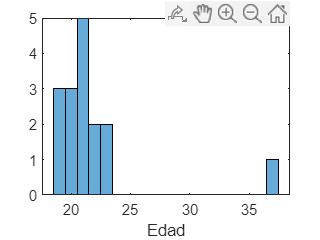

Edadpromedio = 21.8125

mediaEdad = 21

ModaEdad = 21

stdEdad = 4.2461

 figure, histogram(datos.Edad), xlabel('Edad')

Analizando la variable TALLA DE ZAPATO:

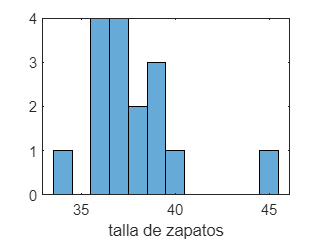

promedioZ = 37.7500

mediaZ = 37

ModaZ = 36

 figure, histogram(datos.Talla_zapatos), xlabel('talla de zapatos')

# gráfico variables cuantitativas

## Histograma

Un histograma proporciona información visual acerca de cómo se distribuye un conjunto de datos. El rango de valores posibles se divide en intervalos, o *bins* y cada barra muestra cuántas observaciones se encuentran dentro de ese intervalo.

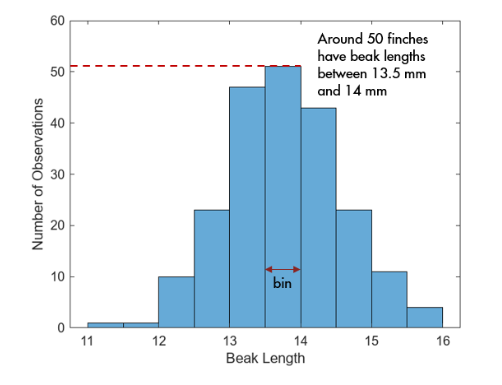

## Actividad:

Separa los datos por género, y crea dos tablas separadas para cada categoría

%data = readtable("Recoleccion_datos_Estadistica.csv");
%data.Species = categorical(data.Species);
%data.Year = categorical(data.Year);
%creando tablas separadas por cada especie
%scandens = data(data.Species == "scandens",:)
%fortis = data(data.Species == "fortis",:)



Parece que el histograma de la talla de los zapatos tiene dos picos, lo que indica que los datos son *bimodales*. Los datos representados corresponden a los dos géneros. Crea histogramas separados de la talla de los zapatos por cada género

% histogram(scandens.BeakLength)
% hold on
% histogram(fortis.BeakLength)
% legend('scandens','Fortis')
% xlabel('Beak Length'), ylabel('Frecuency')
% hold off

%la información de los histogramas siempre debe ser analizada según la naturaleza de los datos
%Puede modificar la anchura de cada uno de los bins especificando el argumento nombre-valor BinWidth.
%histogram(data,BinWidth=0.5)

## función de densidad de probabilidad (pdf) 

Hay más observaciones de un género que de otro. Esta diferencia en el número de observaciones puede suponer un sesgo al comparar los dos grupos. Para corregir este sesgo, puede normalizar el histograma con una estimación de *función de densidad de probabilidad (pdf)* estableciendo el argumento nombre-valor `Normalization` en `"pdf"`.

`histogram``(``data``,``BinWidth``=``0.5``,``...`

           `Normalization``=``"pdf"``)`

Cada uno de los bins del histograma normalizado representa la probabilidad relativa de que se produzcan las observaciones.  

% histogram(scandens.BeakLength(scandens.Year=='1975'),BinWidth=0.5,Normalization="pdf")
% hold on
% histogram(scandens.BeakLength(scandens.Year=='2012'),BinWidth=0.5,Normalization="pdf")
% legend('1975','2012')
% xlabel('Beak Length Scandens'), ylabel('Frecuency')
% hold off
% 
% histogram(fortis.BeakLength(fortis.Year=='1975'),BinWidth=0.5,Normalization="pdf")
% hold on
% histogram(fortis.BeakLength(fortis.Year=='2012'),BinWidth=0.5,Normalization="pdf")
% legend('1975','2012')
% xlabel('Beak Length Fortis'), ylabel('Frecuency')
% hold off

**En las actividades anteriores, (Clase_1.mlx) se presenta la información para crear diagrama de dispersión. Recuerde que los diagramas de dispersión permiten comparar dos variables, mientras que los histogramas ofrecen una visión general de la distribución de los datos. Para visualizar estos dos tipos de gráficas en una sola, se puede utilizar un histograma de dispersión (**`scatterhistogram`**).**

**Presente dichos diagramas de dispersión:**

 scatterhistogram(data.Peso_Kg_,data.G_nero)






## Diagramas de cajas y bigotes

Al igual que los histogramas, los diagramas de cajas representan la distribución de un conjunto de datos, con una ventaja: los diagramas de cajas resumen de forma compacta la distribución de los datos, lo que facilita la comparación de múltiples distribuciones de población.

La caja central representa el 50% medio de las observaciones, y la línea dentro del recuadro es la mediana de los datos o punto medio. Las líneas de "bigotes" muestran la extensión del ≈99% de los datos, si se distribuyen normalmente. Los posibles valores atípicos se representan individualmente con círculos azules.

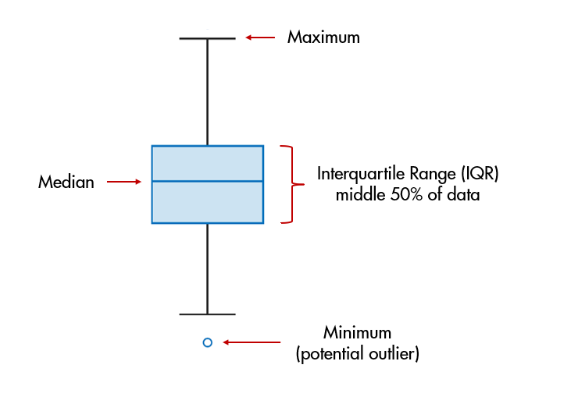

Puede crear un diagrama de cajas mediante la función `boxchart`.

`boxchart``(``groupdata``,``ydata``), el primer argumento es el agrupamiento y el segundo los datos`

%   boxchart(data.Species,data.BeakLength)
% boxchart(data.Species,data.BeakLength)
% xlabel('Species'), ylabel('beak length')


Los diagramas de cajas permiten ver fácilmente las diferencias entre una varible agrupada con otra. Algunas veces hay otra variable que las agrupa, y en ese caso se utiliza un tercer argumento:  el argumento nombre-valor `GroupByColor`.

`boxchart``(``groupdata``,``ydata``,``... `

`GroupByColor``=``cgroupdata``)`

Puede utilizar la función `legend` para añadir una leyenda al diagrama. No es necesario especificar las etiquetas porque `boxchart` las obtiene de la variable categórica utilizada en `GroupByColor`.

%  boxchart(data.Species,data.BeakLength,GroupByColor=data.Year)
% xlabel('Species'), ylabel('beak length')
% legend

# Medidas de centralidad

## Media:

La *media* (también denominada *media aritmética*, o simplemente *promedio*) es una medida común de centralidad. Resulta útil para distribuciones simétricas, pero es sensible a valores atípicos. Si el conjunto de datos no se distribuye simétricamente o presenta valores atípicos extremos, debe considerar cómo afectan estos factores al cálculo de la media.

Para calcular la media, o promedio, se puede utilizar la función `mean`.

`mu` `=` `mean``(``x``)`

 %variable Edad
 Edadpromedio=mean(datos.Edad)
 mediaEdad= median(datos.Edad)
 ModaEdad= mode(datos.Edad)
 stdEdad=std(datos.Edad)

 %Variable Talla de Zapatos 
 promedioZ=mean(datos.Talla_zapatos)
 mediaZ= median(datos.Talla_zapatos)
 ModaZ= mode(datos.Talla_zapatos)


histogramas:

## Mediana: 

La *mediana* representa el punto medio de los datos ordenados, por lo que la mitad de los datos es mayor que la mediana y la otra mitad es menor que la mediana. En comparación con la media, la mediana es mucho más resistente a cambios en unos pocos valores de datos, y es un centro especialmente útil para distribuciones *asimétricas*.

Para calcular la mediana, puede utilizar la función `median`.

`med` `=` `median``(``x``)`

el código a continuación es para visualizar las medias y medianas en el histograma correspondiente a la longitud del pico de esta especie.

% histogram(sLength1975,BinWidth=0.5,Normalization="pdf")
% hold on
% histogram(sLength2012,BinWidth=0.5,Normalization="pdf")
% hold off
% xlabel("Beak Length (mm)")
% legend("1975","2012")
% 
% 

newTable = 2×10 table
     Genero      GroupCount    mean_Edad    median_Edad    mode_Edad    std_Edad    mean_Altura_cm    median_Altura_cm    mode_Altura_cm    std_Altura_cm
    _________    __________    _________    ___________    _________    ________    ______________    ________________    ______________    _____________

    Femenino         12             22          21            19          4.899         159.83               159               158             6.1324    
    Masculino         4          21.25          21            21         1.2583         183.25             180.5               177             8.2614    


% hold on
% xline(m1975,"b")
% xline(med1975,"b:")
% xline(m2012,"r")
% xline(med2012,"r:")
% hold off
% legend("1975","2012","m1975","med1975", ...
%     "m2012","med2012",Location="eastoutside")

# Medidas de dispersión

Según los cálculos de la media y la mediana de la actividad anterior, la edad promedio es de 21.8. Pero ¿qué importancia práctica tiene esta medida? 

La diferencia entre estos escenarios es el grado de *dispersión* de las distribuciones, es decir, cuánto se desvían los datos del centro. Al igual que con las medidas de centralidad, se pueden calcular varias medidas estándar de dispersión.

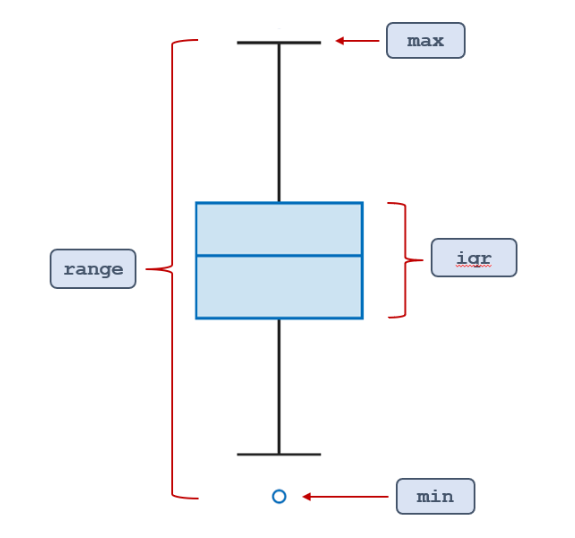

% boxchart(scandens.Year,scandens.BeakLength)
% title("Scandens Beak Length by Year") 

## desviación estándar

La *desviación estándar* se suele utilizar para medir la dispersión de distribuciones simétricas que siguen una curva en campana o *distribución normal*. La desviación estándar tiende a amplificar el efecto de los valores atípicos.

Para calcular la desviación estándar, puede utilizar la función `std`.

`s` `=` `std``(``x``)`

## Rango intercuartil

El *rango intercuartil* se basa en la mediana (el punto correspondiente al percentil 50). Proporciona la distancia entre los percentiles 25 y 75 de los datos, es decir, la anchura de la región que contiene el 50% medio de los valores de los datos.

Al igual que la mediana, el rango intercuartil es resistente a los valores atípicos y especialmente útil para distribuciones asimétricas.

Para calcular el rango intercuartil, puede utilizar la función `iqr`.

`r` `=` `iqr``(``x``)`

## Rango

El *rango* es la diferencia entre los valores máximo y mínimo de los datos. y ofrece una idea aproximada de cuán dispersas están las observaciones más extremas. Por ello, el rango está fuertemente influenciado por la presencia de valores atípicos.

Puede utilizar la función `range` para calcular el rango.

`r` `=` `range``(``x``)`

Los histogramas se pueden diseñar con centro en la media, para esto se le resta a todos los datos el valor de la media, así los datos por debajo son negativos, los datos pro encima son positivos y los dastos igual a la media son cero

% histogram(sLength1975 - mean(sLength1975),...
% BinWidth=0.5,Normalization="pdf")
% hold on
% histogram(sLength2012 - mean(sLength2012),...
% BinWidth=0.5,Normalization="pdf")
% hold off
% legend("1975","2012")
% xlabel("Difference from mean length (mm)")

# Medidas de formas

## Asimetría

La *asimetría* es una medida de la falta de simetría de una distribución. Una asimetría de 0 indica que el conjunto de datos es simétrico. Una asimetría positiva indica que el conjunto de datos tiene más valores extremos mayores que la media, es decir, una cola más larga hacia la derecha. De forma similar, una asimetría negativa indica que el conjunto de datos tiene más valores extremos por debajo que la media, es decir, una cola más larga hacia la izquierda.

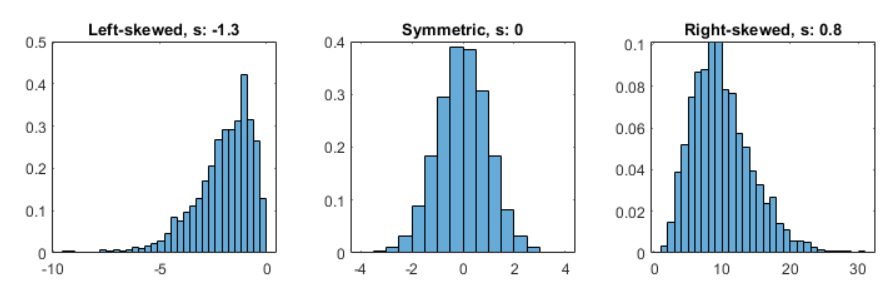

Para calcular la asimetría, puede utilizar la función `skewness`.

`skew` `=` `skewness``(``x``)`

## Curtosis

La *curtosis* es una medida de cuán propensa a tener valores atípicos es una distribución, es decir, la cola de distribución. De forma predeterminada, la curtosis de la distribución normal es 3. Si la distribución tiene un pico más estrecho y colas más gruesas, el valor de curtosis es superior a 3. Un valor por debajo de 3 significa que la distribución muestra un pico más amplio y colas menos gruesas.

     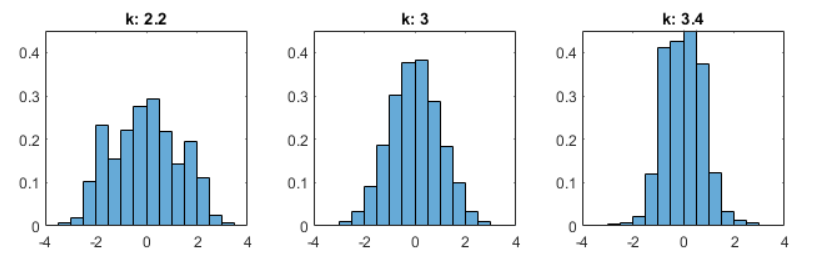

Puede calcular la curtosis utilizando la función `kurtosis`.

`k` `=` `kurtosis``(``x``)`

La asimetría positiva de los datos significa que están ligeramente sesgados a la derecha.

El valor de curtosis inferior a 3, indica que los datos están más concentrados hacia el medio, y se confirma en el cuadro del diagrama de cajas. 

# Calcular múltiples estadísticas para variables agrupadas

La tarea en tiempo real **Compute by Group** permite calcular múltiples estadísticas descriptivas por grupos.

**ACTIVIDAD**

- Abra la tarea en tiempo real **Compute by Group**. En la sección **Code** de la pestaña Live Editor, seleccione **Task**. Luego, en **Preprocessing Data**, seleccione **Compute by Group**.

- En **Group by**, seleccione la tabla `scandens`.

- En la opción que aparece a la derecha, seleccione `Year` como variable de agrupación.

- Cambie el nombre de la variable de salida de esta tabla resumen de `newTable` a `scandensSummary`.

% Compute group summary
newTable = groupsummary(datos,"Genero",["mean","median","mode","std"],["Edad",...
    "Altura_cm"])
